## Simple Linear Regression

Finds a line that fits data.

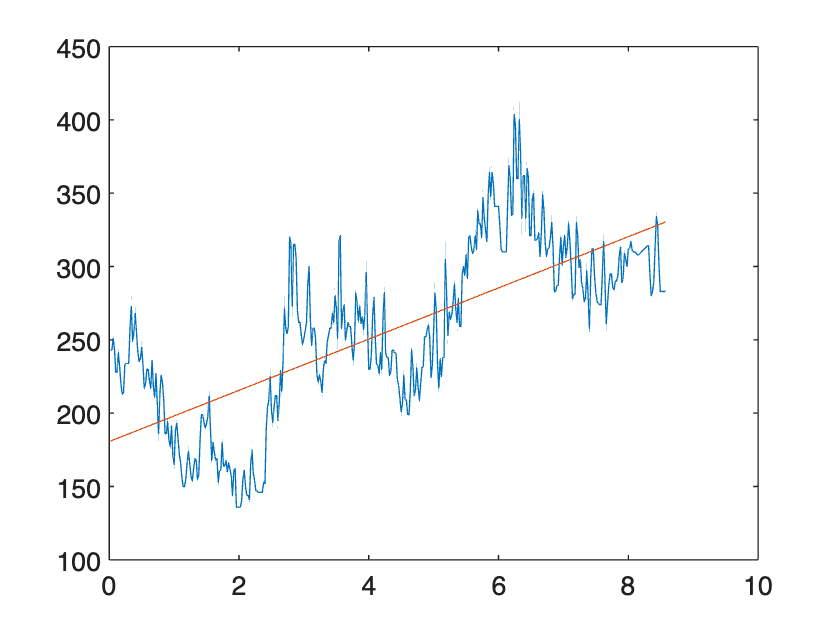

file = readmatrix("./input.csv");
inputs = file(:,1);
measurements = file(:,2);

predictions = linearRegression( ...
    inputs, ...
    measurements ...
);

plot(inputs, measurements, inputs, predictions);

function predictions = linearRegression(inputs, outputs)
  xMean = mean(inputs);
  yMean = mean(outputs);

  xErrors = inputs - xMean;
  xErrorsSquared = xErrors .^2;
  yErrors = outputs - yMean;

  m = sum(xErrors .* yErrors) / sum(xErrorsSquared);
  b = yMean - m * xMean;

  predictions = inputs * m + b;
end
